# LAIIQAToolbox

## Descripción

Programa recortar y graficar los archivos .mat generados del proceso de ozonización desde un tiempo de concentración inicial cero. Para el laboratorio LAIIQA de ESIQIE - IPN.

## Requerimientos de Sistema

Matlab > R2019.

## Instalación

Desde **Add-Ons** en la pestaña **Home**, buscar como **laiiqatoolbox**.

## Caracteristicas

- Programación orientada a objetos.

- Grafica datos ajustados (recortados) a una concentración inicial cero (o cercana).

- Acceso a propiedades de grafico: titulo, etiquetas de ejes *x* y *y, *legenda, tamaño, etc.

- Conversión de tiempo del eje *x: *min, h, seg.

- Multiselección de archivos para grafcar.

- Acceso a variables de datos crudos (`rawdata`) y ajustados (`fixeddata`).

- Calculo de consumo de ozono.

- Acceso a variables de consumo de ozono (`ozoneresults`).

- Guardado de grafico en varios formatos: png, jpg, jpeg, pdf, eps, svg, tif, fig.

- Creación de varios objetos gráficos a la vez.

## Ejemplos

### Creación del objeto

Inicializamos una instancia de objeto de tipo ***laiiqatoolbox***:

clearvars
close all
clc
mivariable1 = laiiqatoolbox

mivariable1 =   laiiqatoolbox with properties:

              rawdata: []
            fixeddata: []
                title: "Cinética de Ozonización"
     titleInterpreter: 'tex'
               xlabel: 'min'
                   xf: {'end'}
               ylabel: "Concentración [g/L]"
     labelInterpreter: 'tex'
                 grid: 'on'
            LineWidth: 0.5000
               legend: {'default'}
       legendFontSize: 8
       legendLocation: 'best'
    legendInterpreter: 'tex'
      imageResolution: 300
         ozoneresults: []
           ozoneUnits: 'g/L'


### Carga de archivos

Cargamos los archivos *.mat* a graficar generados por el ozonograma con el método `openfiles`:

mivariable1.openfiles

ans =   laiiqatoolbox with properties:

              rawdata: {[2×421267 double]  [2×568493 double]  [2×700444 double]}
            fixeddata: []
                title: "Cinética de Ozonización"
     titleInterpreter: 'tex'
               xlabel: 'min'
                   xf: {'end'  'end'  'end'}
               ylabel: "Concentración [g/L]"
     labelInterpreter: 'tex'
                 grid: 'on'
            LineWidth: 0.5000
               legend: {["4CF002_corrida1_500mL_01092021"]  ["4CF003_corrida1_500mL_03092021"]  ["4CF004_corrida1_500mL_14092021"]}
       legendFontSize: 8
       legendLocation: 'best'
    legendInterpreter: 'tex'
      imageResolution: 300
         ozoneresults: []
           ozoneUnits: 'g/L'


### Creación del gráfico

Graficamos los archivos cargados con el método `plotfiles`:

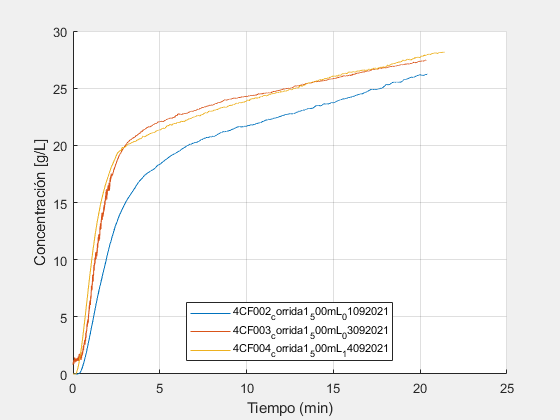

ans =   laiiqatoolbox with properties:

              rawdata: {[2×421267 double]  [2×568493 double]  [2×700444 double]}
            fixeddata: {[2×122365 double]  [2×122122 double]  [2×128430 double]}
                title: ''
     titleInterpreter: 'tex'
               xlabel: 'min'
                   xf: {[25]  [25]  [25]}
               ylabel: "Concentración [g/L]"
     labelInterpreter: 'tex'
                 grid: 'on'
            LineWidth: 0.5000
               legend: {["4CF002_corrida1_500mL_01092021"]  ["4CF003_corrida1_500mL_03092021"]  ["4CF004_corrida1_500mL_14092021"]}
       legendFontSize: 8
       legendLocation: 'best'
    legendInterpreter: 'tex'
      imageResolution: 300
         ozoneresults: []
           ozoneUnits: 'g/L'


mivariable1.plotfiles

### Moficación de las propiedades del objeto

Para modificar el titulo del gráfico:

mivariable1.title = 'Mi Grafico 1'

mivariable1 =   laiiqatoolbox with properties:

              rawdata: {[2×421267 double]  [2×568493 double]  [2×700444 double]}
            fixeddata: {[2×393631 double]  [2×540614 double]  [2×678873 double]}
                title: 'Mi Grafico 1'
     titleInterpreter: 'tex'
               xlabel: 'min'
                   xf: {'end'  'end'  'end'}
               ylabel: "Concentración [g/L]"
     labelInterpreter: 'tex'
                 grid: 'on'
            LineWidth: 0.5000
               legend: {["4CF002_corrida1_500mL_01092021"]  ["4CF003_corrida1_500mL_03092021"]  ["4CF004_corrida1_500mL_14092021"]}
       legendFontSize: 8
       legendLocation: 'best'
    legendInterpreter: 'tex'
      imageResolution: 300
         ozoneresults: []
           ozoneUnits: 'g/L'


Para quitar el titulo del gráfico:

mivariable1.title = '' % Dloble coma sencilla para dejar el titulo vacío

mivariable1 =   laiiqatoolbox with properties:

              rawdata: {[2×421267 double]  [2×568493 double]  [2×700444 double]}
            fixeddata: {[2×393631 double]  [2×540614 double]  [2×678873 double]}
                title: ''
     titleInterpreter: 'tex'
               xlabel: 'min'
                   xf: {'end'  'end'  'end'}
               ylabel: "Concentración [g/L]"
     labelInterpreter: 'tex'
                 grid: 'on'
            LineWidth: 0.5000
               legend: {["4CF002_corrida1_500mL_01092021"]  ["4CF003_corrida1_500mL_03092021"]  ["4CF004_corrida1_500mL_14092021"]}
       legendFontSize: 8
       legendLocation: 'best'
    legendInterpreter: 'tex'
      imageResolution: 300
         ozoneresults: []
           ozoneUnits: 'g/L'


Para aplicar los cambios ejecutamos el método `plotfiles` de nuevo:

mivariable1.plotfiles; % Con ; evitamos mostrar la salida en el Command Window

mivariable1

mivariable1 =   laiiqatoolbox with properties:

              rawdata: {[2×421267 double]  [2×568493 double]  [2×700444 double]}
            fixeddata: {[2×92365 double]  [2×540614 double]  [2×678873 double]}
                title: ''
     titleInterpreter: 'tex'
               xlabel: 'min'
                   xf: {[20]  [20]  [20]}
               ylabel: "Concentración [g/L]"
     labelInterpreter: 'tex'
                 grid: 'on'
            LineWidth: 0.5000
               legend: {["4CF002_corrida1_500mL_01092021"]  ["4CF003_corrida1_500mL_03092021"]  ["4CF004_corrida1_500mL_14092021"]}
       legendFontSize: 8
       legendLocation: 'best'
    legendInterpreter: 'tex'
      imageResolution: 300
         ozoneresults: []
           ozoneUnits: 'g/L'
